# Swing by Venus - Numerik Abschlussprojekt

Urs Müller, Joachim Spitaler, Leonie Graf

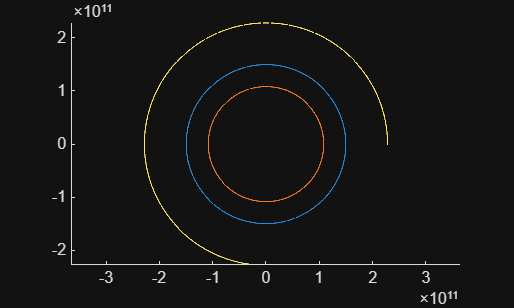

clear all, close all, clc, clf  
r_Mars  = 227990000*10^3;  % Mittlerer Bahnradius Mars 
T_Mars = 686.980; % Tage

tspan = linspace(0,500,10000);

Earth = posEarth(tspan);
Venus = posVenus(tspan);
Mars = posMars(tspan);

figure;
hold on;
plot(Earth(:,1), Earth(:,2));
plot(Venus(:,1), Venus(:,2));
plot(Mars(:,1), Mars(:,2));
axis equal;

Abstand 1% und so

%Startposition der Venus abgreifen
rV = posVenus(0)';
dmin = 1e5;
dmax = 1e12;

f = @(d) venus_ratio(d,rV);
dsolve = fzero(f,[dmin;dmax]);
fprintf("Abstand zu Venus bei 0.01 der Gravitation = %.1f km",dsolve/1000)

Abstand zu Venus bei 0.01 der Gravitation = 1693196.3 km

Bahnkurve Sonde, Start tangential zu Erdlaufbahn

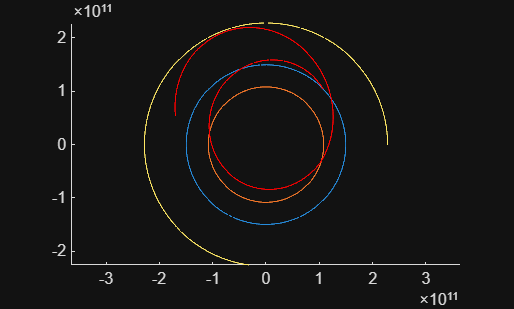

v0 = 13.333 * 10^3 * 86400; %Startgeschwindigkeit, Meter/Tage
angle = -1.611720;
options = odeset("AbsTol",1e-14, "RelTol",1e-12, "MaxStep", 0.01);

% Funktion addiert Erdgeschwindigkeit, richtet nach Winkel aus
[pos, v0_vec] = v0_calc(v0, angle);
[t, y] = ode15s(@grav_calc, tspan, [pos'; v0_vec], options);
plot(y(:,1), y(:,2), "r-");


rS = y(:,1:2);              % Satellit
rV = posVenus(t);           

d = vecnorm(rV - rS, 2, 2);  % euklidische Distanz je Zeitpunkt
distMin = min(d);

fprintf("Minimale Distanz zu Venus: %.2f", distMin/1000)

Minimale Distanz zu Venus: 13380.96

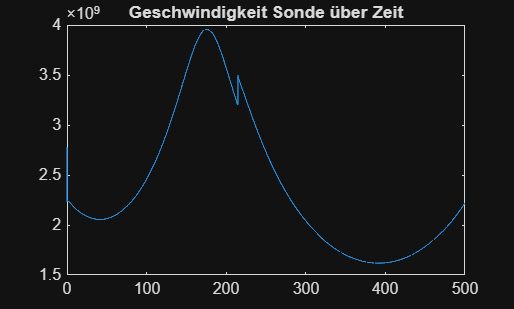


speed = vecnorm(y(:,3:4),2,2);
figure;
hold off;
plot(t, speed)
title("Geschwindigkeit Sonde über Zeit")


[t_sun, y_sun] = ode45(@grav_sun, tspan, [pos'; v0_vec]);
%plot(y_sun(:,1), y_sun(:,2), "g");

Aufgabe, Venus in Abstand von 20000km passieren

v0 = 13.333 * 10^3 * 86400; %Startgeschwindigkeit, Meter/Tage
angles = linspace(-1.61171, -1.61173, 1000);
results = zeros(length(angles), 2); %Vektor für Ergebnisse

options = odeset('AbsTol',1e-14, "RelTol",1e-12, "MaxStep", 0.01, "Events", @(t,y) swinger(t,y));

hit = false(length(angles),1);
minDist = inf(length(angles),1);   % minimale Distanz pro Winkel

% for j = 1:length(angles)
% 
%     [pos, v0_vec] = v0_calc(v0, angles(j));
%     y0 = [pos(:); v0_vec(:)];
% 
%     [t, y, te, ye, ie] = ode15s(@grav_calc, tspan, y0, options);
% 
%     rS = y(:,1:2);              % Satellit
%     rV_all = posVenus(t);           % Venus (Nx2)
% 
%     d_all = vecnorm(rV_all - rS, 2, 2);  % euklidische Distanz je Zeitpunkt
%     minDist(j) = min(d_all);
% 
%     if ~isempty(te)
%         hit(j) = true;
%     end
% end
% 
% best_angles = angles(hit);
% best_minDist = minDist(hit);
% 
% for k = 1:length(best_angles)
%     fprintf("Winkel = %.7f rad (%.2f°), min. Distanz = %.0f km\n", best_angles(k), rad2deg(best_angles(k)), best_minDist(k)/1000);
% end

function [val, term, dir] = swinger(t, y)
    target = 20000 * 10^3;  %Zieldistanz in Metern

    rS = y(1:2)';           %Als Zeilenvektor speichern
    rV = posVenus(t);
    dist = norm(rV - rS);

    val = target - dist;                  %Toleranz, ode45 löst System nur an bestimmten Zeitschritten
    term = 1;                             %Stoppen
    dir = -1;
end